# 第一周作业模板：计及配电网二阶锥潮流与充放电互斥约束 (MISOCP) 的储能日前优化调度

课程名称：《储能优化配置与调度技术》课程设计

## 0. 模板使用说明与核心数学模型

**使用说明**：

- 请将本模板复制到 `ESS-Course-Submissions` 仓库下你的 【学号_姓名拼音】 文件夹中；

- 重命名为 【姓名拼音_学号_Week1.mlx】，并修改第 2 节中的 `Stu_ID` 为本人真实 9 位学号；

- 仔细阅读各节的 LaTeX 数学模型说明，在标有 `% 【TODO】` 的代码块处补全核心建模语句，并导出对应的 `.m` 纯文本脚本一并提交。

**核心数学模型**：

**1) 储能系统荷电状态（SoC）动态递推方程与充放电互斥约束**（已知单站额定功率 $P_i^{\mathrm{rated}}$、额定容量 $E_i^{\mathrm{rated}}$ 为常数，引入二进制互斥变量 $u_{i,t}^{\mathrm{ch}} \in \{0,1\}$）：


$$\mathrm{SoC}_{i,t} = \mathrm{SoC}_{i,t-1} + \frac{\eta_{\mathrm{ch}} P_{i,t}^{\mathrm{ch}} \Delta t}{E_i^{\mathrm{rated}}} - \frac{P_{i,t}^{\mathrm{dis}} \Delta t}{\eta_{\mathrm{dis}} E_i^{\mathrm{rated}}}, \quad \mathrm{SoC}_{\min} \le \mathrm{SoC}_{i,t} \le \mathrm{SoC}_{\max}$$



$$0 \le P_{i,t}^{\mathrm{ch}} \le u_{i,t}^{\mathrm{ch}} P_i^{\mathrm{rated}}, \quad 0 \le P_{i,t}^{\mathrm{dis}} \le \left(1 - u_{i,t}^{\mathrm{ch}}\right) P_i^{\mathrm{rated}}, \quad u_{i,t}^{\mathrm{ch}} \in \{0,1\}$$


**2) 配电网 DistFlow 支路潮流与旋转二阶锥松弛方程**（令 $U_{i,t} = V_{i,t}^2, L_{ij,t} = I_{ij,t}^2$）：


$$P_{ij,t} - r_{ij} L_{ij,t} - \sum_{k\in\delta(j)} P_{jk,t} = P_{j,t}^{\mathrm{load}} - P_{j,t}^{\mathrm{pv}} + P_{j,t}^{\mathrm{ch}} - P_{j,t}^{\mathrm{dis}}$$



$$Q_{ij,t} - x_{ij} L_{ij,t} - \sum_{k\in\delta(j)} Q_{jk,t} = Q_{j,t}^{\mathrm{load}}$$



$$U_{j,t} = U_{i,t} - 2\left(r_{ij} P_{ij,t} + x_{ij} Q_{ij,t}\right) + \left(r_{ij}^2 + x_{ij}^2\right) L_{ij,t}$$



$$\sqrt{\left(2P_{ij,t}\right)^2 + \left(2Q_{ij,t}\right)^2 + \left(L_{ij,t} - U_{i,t}\right)^2} \le L_{ij,t} + U_{i,t}, \quad \left(V_{\min}\right)^2 \le U_{i,t} \le \left(V_{\max}\right)^2$$


clear; clc; close all;
yalmip('clear');
%----------------------------请修改地址------------------------------
addpath("E:\clone\ESS-Course-Submissions\206231314_Liyichen")
%-------------------------------------------------------------------

## 1. 自动检测算例库是否已在 MATLAB 搜索路径中

if ~exist('case_nongcun.m', 'file')
    % 若不在路径中，弹窗提示学生选择一次本地的 ESS-Course-Materials/cases 文件夹
    case_dir = uigetdir(pwd, '请选择教学资源库中的 cases 文件夹路径');
    addpath(case_dir);
end

## 2. 学号映射与网络参数读取

**【学生修改区】**：请将下方 `Stu_ID` 修改为你本人的 9 位学号！程序将根据末两位 $\mathrm{XY}$ 自动计算负荷缩放乘子 $\alpha = 1 + 0.002 \times \mathrm{XY}$ 并分配专属算例。

Stu_ID  = 206231314;
XY      = mod(Stu_ID, 100);
X_digit = floor(XY / 10);
Y_digit = mod(XY, 10);
alpha   = 1 + 0.002 * XY;

if ismember(Y_digit, [0, 1, 2, 3])
    case_name = 'case_nongcun';
elseif ismember(Y_digit, [4, 5, 6])
    case_name = 'case_chengshi_A';
else
    case_name = 'case_kaifaqu_A';
end
mpc = loadcase(case_name);
load('profiles_24h.mat');

if ismember(X_digit, [0, 1, 2])
    ess_buses  = [4, 9, 14];
    model_type = 'A'; % 模型 A：最大化新能源消纳（含微网损正则项）
elseif ismember(X_digit, [3, 4, 5])
    ess_buses  = [5, 11, 16];
    model_type = 'B'; % 模型 B：最小化全网有功网损
else
    ess_buses  = [6, 13, 17];
    model_type = 'C'; % 模型 C：最小化主网购电成本
end
pv_buses = ess_buses;

## 3. 标幺值基准转换与设备参数设置

Sbase = mpc.baseMVA;
N_bus = size(mpc.bus, 1);
N_br  = size(mpc.branch, 1);
N_ess = length(ess_buses);
N_pv  = length(pv_buses);

fbus = mpc.branch(:, 1);
tbus = mpc.branch(:, 2);
r_br = mpc.branch(:, 3);
x_br = mpc.branch(:, 4);

Pd_pu       = (mpc.bus(:, 3) * alpha / Sbase) * load_curve_pu';
Qd_pu       = (mpc.bus(:, 4) * alpha / Sbase) * load_curve_pu';
P_pv_max_pu = (1.2 / Sbase) * repmat(pv_curve_pu', N_pv, 1);

P_ess_rated_pu = 1.5 / Sbase; % 单站固定额定功率 1.5 MW (标幺值)
E_ess_rated_pu = 3.0 / Sbase; % 单站固定额定容量 3.0 MWh (标幺值)
eta_ch  = 0.90;
eta_dis = 0.95;
SoC_min = 0.20;
SoC_max = 0.80;
SoC_0   = 0.50;

## 4. 声明 YALMIP 决策变量

U_bus  = sdpvar(N_bus, T, 'full'); % 节点电压平方 U_{i,t} = V_{i,t}^2
L_br   = sdpvar(N_br,  T, 'full'); % 支路电流平方 L_{ij,t} = I_{ij,t}^2
P_br   = sdpvar(N_br,  T, 'full'); % 支路首端有功功率 (p.u.)
Q_br   = sdpvar(N_br,  T, 'full'); % 支路首端无功功率 (p.u.)
P_grid = sdpvar(1,     T, 'full'); % 关口有功功率 (p.u.)
Q_grid = sdpvar(1,     T, 'full'); % 关口无功功率 (p.u.)
P_ch   = sdpvar(N_ess, T, 'full'); % 储能充电有功功率 (p.u.)
P_dis  = sdpvar(N_ess, T, 'full'); % 储能放电有功功率 (p.u.)
u_ch   = binvar(N_ess, T, 'full'); % 储能充放电互斥二进制变量 u_{i,t}^{ch} \in {0,1}
SoC    = sdpvar(N_ess, T, 'full'); % 储能荷电状态 SoC_{i,t}
P_pv   = sdpvar(N_pv,  T, 'full'); % 分布式光伏实际出力 (p.u.)

## 5. 构建约束条件

## 5.1 储能充放电互斥与分布式光伏运行约束

Constraints = [];
Constraints = [Constraints, 0 <= P_ch  <= P_ess_rated_pu * u_ch];
Constraints = [Constraints, 0 <= P_dis <= P_ess_rated_pu * (1 - u_ch)];
Constraints = [Constraints, SoC_min <= SoC <= SoC_max];
Constraints = [Constraints, SoC(:, T) == SoC_0];
Constraints = [Constraints, 0 <= P_pv <= P_pv_max_pu];

for t = 1:T
    if t == 1
        soc_prev = repmat(SoC_0, N_ess, 1);
    else
        soc_prev = SoC(:, t - 1);
    end
    % 【TODO 1】请在此处补全储能荷电状态 SoC(:, t) 的跨时段耦合递推方程：
    Constraints = [Constraints, SoC(:, t) == soc_prev + ...
        (eta_ch * P_ch(:, t) - P_dis(:, t) / eta_dis) / E_ess_rated_pu];
end

## 5.2 节点功率平衡与 DistFlow 二阶锥潮流约束

A_from  = sparse(fbus, 1:N_br, 1, N_bus, N_br);
A_to    = sparse(tbus, 1:N_br, 1, N_bus, N_br);
A_ess   = sparse(ess_buses, 1:N_ess, 1, N_bus, N_ess);
A_pv    = sparse(pv_buses,  1:N_pv,  1, N_bus, N_pv);
A_slack = sparse(1, 1, 1, N_bus, 1);

P_loss_br = diag(r_br) * L_br;
Q_loss_br = diag(x_br) * L_br;

Constraints = [Constraints, A_to * (P_br - P_loss_br) - A_from * P_br + ...
    A_slack * P_grid + A_pv * P_pv + A_ess * (P_dis - P_ch) == Pd_pu];
Constraints = [Constraints, A_to * (Q_br - Q_loss_br) - A_from * Q_br + ...
    A_slack * Q_grid == Qd_pu];

Constraints = [Constraints, U_bus(1, :) == 1.0];
Constraints = [Constraints, (0.95^2) <= U_bus(2:end, :) <= (1.05^2)];
Constraints = [Constraints, L_br >= 0];

for b = 1:N_br
    i = fbus(b);
    j = tbus(b);
    % 【TODO 2】请核对并掌握 DistFlow 支路电压平方降落方程与 cone 二阶锥松弛约束：
    Constraints = [Constraints, U_bus(j, :) == U_bus(i, :) - ...
        2 * (r_br(b) * P_br(b, :) + x_br(b) * Q_br(b, :)) + ...
        (r_br(b)^2 + x_br(b)^2) * L_br(b, :)];
    for t = 1:T
        Constraints = [Constraints, cone([2 * P_br(b, t); 2 * Q_br(b, t); ...
            L_br(b, t) - U_bus(i, t)], L_br(b, t) + U_bus(i, t))];
    end
end

## 6. 构建目标函数并调用 MISOCP 求解器 (MOSEK / Gurobi)

本模型同时包含充放电互斥二进制变量 $u_{i,t}^{\mathrm{ch}}$ 与支路二阶锥约束，属于混合整数二阶锥规划（MISOCP），需调用 MOSEK 或 Gurobi 求解。若使用 CVX 随附的 MOSEK，请仅将 `cvx/mosek` 子文件夹加入 MATLAB 路径（|addpath(genpath('.../cvx/mosek'))|），切勿运行 `cvx_setup` 或添加 `cvx` 根目录。

Total_Loss_MWh    = Sbase * sum(sum(P_loss_br));
Total_Curtail_MWh = Sbase * sum(sum(P_pv_max_pu - P_pv));
Total_Cost_Yuan   = sum((Sbase * P_grid') .* price_MWh);

% 【TODO 3】根据本人学号映射的 model_type ('A' / 'B' / 'C') 选择目标函数：
if strcmp(model_type, 'A')
    Objective = Total_Curtail_MWh + 1e-2 * Total_Loss_MWh;
elseif strcmp(model_type, 'B')
    Objective = Total_Loss_MWh + 1e-4 * sum(sum(P_ch + P_dis));
else
    Objective = Total_Cost_Yuan;
end

solver_candidates={};
if exist('mosekopt','file')~=0,solver_candidates{end+1}='mosek';end
if exist('gurobi','file')~=0,solver_candidates{end+1}='gurobi';end
assert(~isempty(solver_candidates),...
    '本任务含充放电二进制变量和二阶锥约束，需配置 MOSEK 或 Gurobi。');
messages=cell(0,1);solver_succeeded=false;tic;
for k=1:numel(solver_candidates)
    solver_name=solver_candidates{k};
    ops=sdpsettings('solver',solver_name,'verbose',1,'savesolveroutput',1);
    % 由本函数捕获原始异常，既保留错误原因，也继续尝试下一个求解器。
    ops.debug=1;
    if strcmp(solver_name,'mosek')
        ops.mosek.MSK_DPAR_MIO_MAX_TIME=600;
        ops.mosek.MSK_DPAR_MIO_TOL_REL_GAP=1e-6;
        ops.mosek.MSK_DPAR_MIO_TOL_ABS_GAP=1e-8;
        ops.mosek.MSK_DPAR_MIO_TOL_FEAS=1e-9;
        ops.mosek.MSK_DPAR_MIO_TOL_ABS_RELAX_INT=1e-9;
        ops.mosek.MSK_DPAR_INTPNT_CO_TOL_PFEAS=1e-10;
        ops.mosek.MSK_DPAR_INTPNT_CO_TOL_DFEAS=1e-10;
        ops.mosek.MSK_DPAR_INTPNT_CO_TOL_REL_GAP=1e-10;
    else
        % 旧版 YALMIP 默认值为 -1，新版 Gurobi 要求非负。
        ops.gurobi.TuneTimeLimit=0;
        ops.gurobi.TimeLimit=120;
        ops.gurobi.MIPGap=1e-6;
        ops.gurobi.FeasibilityTol=1e-9;
        ops.gurobi.IntFeasTol=1e-9;
        ops.gurobi.OptimalityTol=1e-8;
        ops.gurobi.BarQCPConvTol=1e-9;
    end
    try
        sol=optimize(Constraints,Objective,ops);
    catch solver_error
        messages{end+1}=sprintf('%s [%s]: %s',solver_name,...
            solver_error.identifier,solver_error.message); %#ok<AGROW>
        continue
    end
    if sol.problem==0,solve_seconds=toc;solver_succeeded=true;break;end
    detail=sol.info;
    if isfield(sol,'solveroutput') && ~isempty(sol.solveroutput)
        % MOSEK 的 rcode/rmsg/rcodestr 及终止状态保留在原始输出中。
        detail=sprintf('%s\n原始求解器输出：\n%s',detail,evalc('disp(sol.solveroutput)'));
        if strcmp(solver_name,'mosek') && isfield(sol.solveroutput,'res')
            raw=sol.solveroutput.res;
            detail=sprintf('%s\nMOSEK 返回信息：\n%s',detail,evalc('disp(raw)'));
            if isfield(raw,'sol') && isfield(raw.sol,'int')
                integer_solution=raw.sol.int;
                if isfield(integer_solution,'prosta')
                    detail=sprintf('%s\n整数问题状态：%s',detail,integer_solution.prosta);
                end
                if isfield(integer_solution,'solsta')
                    detail=sprintf('%s\n整数解状态：%s',detail,integer_solution.solsta);
                end
            end
            if isfield(raw,'rcode') && raw.rcode==100001
                detail=sprintf('%s\nMOSEK 已达到本次设置的 %g 秒时间上限。',...
                    detail,ops.mosek.MSK_DPAR_MIO_MAX_TIME);
            end
        end
    end
    messages{end+1}=[solver_name ': ' detail]; %#ok<AGROW>
end


MOSEK Version 11.2.7 (Build date: 2026-10-23 14:10:56)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 6003            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 528             
  Scalar variables       : 4656            
  Matrix variables       : 0               
  Integer variables      : 72              

Optimizer started.
Mixed integer optimizer started.
Threads used: 14
Presolve started.
Presolve terminated. Time = 0.07, probing time =  0.01
Presolved problem: 2205 variables, 1848 constraints, 6066 non-zeros
Presolved problem: 0 general integer, 72 binary, 2133 continuous
Presolved problem: 336 cones
Clique table size: 0
Removed blocks   : 24
BRANCHES RELAXS   ACT_NDS  DEPTH    BEST_INT_OBJ        

if ~solver_succeeded
    error('MISOCP 求解失败：%s',strjoin(messages,'; '));
end

## 7. 二阶锥松弛精确性分析、交流潮流回代与《中国电机工程学报》规范绘图

请注意图片字体与符号规范：中文采用宋体，西文与数字采用 Times New Roman，变量符号采用斜体，单位与下标说明采用正体。

socp_gap     = max(max(abs(value(L_br) .* value(U_bus(fbus, :)) - (value(P_br).^2 + value(Q_br).^2))));
simul_err_MW = max(max(min(value(P_ch), value(P_dis)))) * Sbase;

V_socp_pu     = sqrt(value(U_bus));
V_ac_ess      = zeros(N_bus, T);
Ploss_ac_MWh  = 0;
P_net_ess_MW  = Sbase * value(P_dis - P_ch);
P_pv_MW_val   = Sbase * value(P_pv);
mpopt = mpoption('verbose', 0, 'out.all', 0);
for t = 1:T
    mpc_t = mpc;
    mpc_t.bus(:, 3) = Pd_pu(:, t) * Sbase;
    mpc_t.bus(:, 4) = Qd_pu(:, t) * Sbase;
    mpc_t.bus(pv_buses,  3) = mpc_t.bus(pv_buses,  3) - P_pv_MW_val(:, t);
    mpc_t.bus(ess_buses, 3) = mpc_t.bus(ess_buses, 3) - P_net_ess_MW(:, t);
    res_t = runpf(mpc_t, mpopt);
    V_ac_ess(:, t) = res_t.bus(:, 8);
    Ploss_ac_MWh   = Ploss_ac_MWh + sum(real(get_losses(res_t)));
end
max_ac_v_err = max(max(abs(V_socp_pu - V_ac_ess)));

fprintf('\n================ 第一周：配电网储能 MISOCP 优化调度结果 ================\n');


================ 第一周：配电网储能 MISOCP 优化调度结果 ================


fprintf('学号: %d | 算例: %s | 模型: %s | 求解器: %s\n', Stu_ID, case_name, model_type, solver_name);

学号: 206231314 | 算例: case_chengshi_A | 模型: A | 求解器: mosek


fprintf('模型全天电能损耗: %.4f MWh | 交流潮流电能损耗: %.4f MWh | 弃光量: %.4f MWh | 关口购电成本: %.2f 元\n', ...
    value(Total_Loss_MWh), Ploss_ac_MWh, value(Total_Curtail_MWh), value(Total_Cost_Yuan));

模型全天电能损耗: 0.3545 MWh | 交流潮流电能损耗: 0.3545 MWh | 弃光量: -0.0000 MWh | 关口购电成本: 16428.68 元


fprintf('同时充放电最大重叠功率: %.2e MW | 最大二阶锥松弛间隙: %.2e p.u.\n', simul_err_MW, socp_gap);

同时充放电最大重叠功率: 0.00e+00 MW | 最大二阶锥松弛间隙: 2.06e-09 p.u.


fprintf('交流潮流节点电压范围: [%.4f, %.4f] p.u. | 模型与交流电压最大偏差: %.2e p.u.\n', ...
    min(V_ac_ess(:)), max(V_ac_ess(:)), max_ac_v_err);

交流潮流节点电压范围: [0.9720, 1.0175] p.u. | 模型与交流电压最大偏差: 2.87e-08 p.u.


if socp_gap > 1e-4
    fprintf('[教学提示] 当前模型(%s)目标函数不含网损正惩罚，高光伏时段节点电压触及上限，出现二阶锥松弛不精确与交流电压越限特例。\n', model_type);
end
fprintf('========================================================================\n');

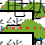


P_net_MW_val = Sbase * value(P_dis - P_ch)';
SoC_pct_val  = value(SoC)' * 100;
line_styles  = {'-o', '-s', '-^'};
colors       = [0.00, 0.45, 0.74; 0.85, 0.33, 0.10; 0.47, 0.67, 0.19];

fig1 = figure('Name', '配电网储能日前SOCP调度结果', 'Color', 'w', 'Position', [120, 100, 720, 500]);
if isprop(fig1, 'Theme'), theme(fig1, 'light'); end

subplot(2, 1, 1);
hold on;
for k = 1:N_ess
    plot(1:T, P_net_MW_val(:, k), line_styles{k}, 'Color', colors(k, :), ...
        'LineWidth', 1.6, 'MarkerSize', 5, 'MarkerFaceColor', colors(k, :));
end
yline(0, '--k', 'LineWidth', 0.9);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'XTick', 0:4:24, 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([1, T]);
ylim([min([P_net_MW_val(:); -0.5]) - 0.25, max([P_net_MW_val(:); 0.5]) + 0.55]);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}储能净放电功率 \fontname{Times New Roman}{\itP}_{\rm{ess}}\rm{/MW}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
title(sprintf('\\fontname{宋体}(a) 各候选节点储能日前调度有功出力 (模型 \\fontname{Times New Roman}%s)', model_type), ...
    'FontSize', 11.5, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
leg_str_a = arrayfun(@(b) sprintf('\\fontname{宋体}节点 \\fontname{Times New Roman}%d \\fontname{宋体}储能', b), ...
    ess_buses, 'UniformOutput', false);
leg1 = legend(leg_str_a, 'Location', 'north', 'Orientation', 'horizontal', 'FontSize', 10, 'Interpreter', 'tex', 'Box', 'on');
set(leg1, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', 'k');
grid on;

subplot(2, 1, 2);
hold on;
for k = 1:N_ess
    plot(1:T, SoC_pct_val(:, k), line_styles{k}, 'Color', colors(k, :), ...
        'LineWidth', 1.6, 'MarkerSize', 5, 'MarkerFaceColor', colors(k, :));
end
yline(SoC_min * 100, ':k', 'LineWidth', 1.1);
yline(SoC_max * 100, ':r', 'LineWidth', 1.1);
set(gca, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'FontName', 'Times New Roman', 'FontSize', 10.5, 'LineWidth', 1.0, ...
    'Box', 'on', 'TickDir', 'in', 'XTick', 0:4:24, 'GridLineStyle', '--', 'GridAlpha', 0.3, 'GridColor', [0.4, 0.4, 0.4]);
xlim([1, T]);
ylim([10, 98]);
xlabel('\fontname{宋体}时间 \fontname{Times New Roman}{\itt}\rm{/h}', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
ylabel('\fontname{宋体}荷电状态 \fontname{Times New Roman}\rm{SoC}/%', 'FontSize', 11.5, 'Color', 'k', 'Interpreter', 'tex');
title('\fontname{宋体}(b) 各候选节点储能荷电状态 \fontname{Times New Roman}\rm{SoC} \fontname{宋体}时序变化曲线', ...
    'FontSize', 11.5, 'FontWeight', 'normal', 'Color', 'k', 'Interpreter', 'tex');
leg2 = legend(leg_str_a, 'Location', 'north', 'Orientation', 'horizontal', 'FontSize', 10, 'Interpreter', 'tex', 'Box', 'on');
set(leg2, 'Color', 'w', 'TextColor', 'k', 'EdgeColor', 'k');
grid on;

% 默认自动导出高质量白底 PNG (600 dpi)、矢量 PDF 与 MATLAB 源文件 FIG
exportgraphics(fig1, sprintf('Fig_Week1_Dispatch_%d.png', Stu_ID), 'Resolution', 600, 'BackgroundColor', 'white');
exportgraphics(fig1, sprintf('Fig_Week1_Dispatch_%d.pdf', Stu_ID), 'ContentType', 'vector', 'BackgroundColor', 'white');

savefig(fig1, sprintf('Fig_Week1_Dispatch_%d.fig', Stu_ID));